addpath(genpath('../../helpers'));

fprintf('Loading FISSA .mat output at %s... \n', phoPipelineOptions.fissa.default_fissa_file_path)
loaded_fissa_data = load(phoPipelineOptions.fissa.default_fissa_file_path);
disp('done.')
        

num_pixels_per_mask = sum(final_data_explorer_obj.compMasks.Masks, [2 3]); 
table(num_pixels_per_mask)


% Consider finalDataStruct.anm265.session_20200120.imgData.comp20.fissa_ROI_regions
finalDataStruct.anm265.session_20200120.imgData.comp20.fissa_ROI_regions

cellfun(@size, finalDataStruct.anm265.session_20200120.imgData.comp20.fissa_ROI_regions,'UniformOutput',false)

% Maps across all trials for this cell_id:
cell_names = fieldnames(loaded_fissa_data.ROIs);
curr_cell_id_name = cell_names{3};
curr_cell_field_sizes = structfun(@size, loaded_fissa_data.ROIs.(curr_cell_id_name),'UniformOutput',false)

curr_cell_field_sizes = structfun(@size, loaded_fissa_data.ROIs.(curr_cell_id_name),'UniformOutput',false)
C = struct2cell(curr_cell_field_sizes)
% template_item = C{1};
% are_all_equal = cellfun(@(c) (isequal(c, template_item)), C)

[all_equal] = cellAllEqual(C)

curr_trial_fieldname = fieldnames(loaded_fissa_data.ROIs.(curr_cell_id_name)) % Just the first item
curr_trial_cell_ROI_regions = loaded_fissa_data.ROIs.(curr_cell_id_name).(curr_trial_fieldname{1})
curr_cell_region_field_sizes = cellfun(@size, curr_trial_cell_ROI_regions,'UniformOutput',false)
[all_equal] = cellAllEqual(curr_cell_region_field_sizes)


[cleaned_curr_trial_cell_ROI_regions] = cleanUp_Imported_FISSA_ROIs(curr_trial_cell_ROI_regions)

cleaned_curr_trial_cell_ROI_regions = 1×5 cell array
    {1×4 cell}    {1×1 cell}    {1×1 cell}    {1×1 cell}    {1×1 cell}


## Custom Plotting

% import PhoCustomPlotComponentBase
% 
% dates = datetime( 1970, 1, 1 ) : datetime( 1980, 1, 1 );
% rng default
% steps = [0, randn( size( dates(1:end-1) ) )];
% walk = cumsum( steps );
% f = exampleFigure( 'Name', 'PhoCustomPlotComponentBase Example' );
% LG = PhoCustomPlotComponentBase( 'Parent', f, ...
%                    'XData', dates, ...
%                    'YData', walk );
% set( LG.XLabel, 'String', 'Date', 'FontSize', 14 )
% set( LG.YLabel, 'String', 'Value', 'FontSize', 14 )
% set( LG.Title, 'String', 'PhoCustomPlotComponentBase', 'FontSize', 16 )
% LG.Grid = 'on';


% x = 1:1:100;
% y = 10*sin(x./5) + 8*sin(10.*x + 0.5);
% c = SmoothPlot('XData',x,'YData',y);

x = 0:0.2:10;
y = besselj(0,x);
c = ConfidenceChart('XData',x,'YData',y,'ConfidenceMargin',0.15);

x = 1:1:100;
y = 10*sin(x./5)+8*sin(10.*x+0.5);
c = PhoSmoothLegendPlot('XData',x,'YData',y);

%%
% Use |c| to change the color of the smooth line to red. Notice that the legend also shows the new line color.

c.SmoothColor = [1 0 0];



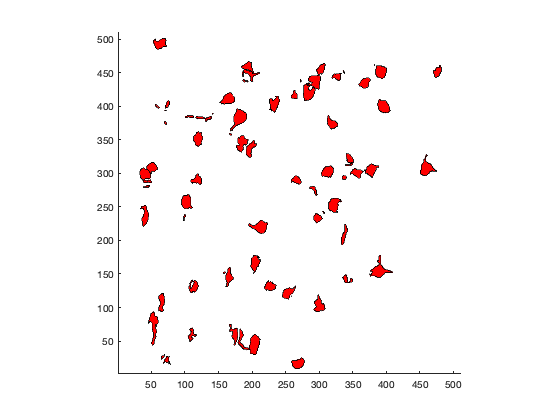

figH = figure(4);
clf(figH, ...
    'reset');

axis square
xlim('manual');
ylim('manual');
hold on;    

activeRoiCells = final_data_explorer_obj.compMasks.Polygons;
for i = 1:length(activeRoiCells)
    currCellPolys = activeRoiCells{i};
    for j = 1:length(currCellPolys)
        curr_poly = currCellPolys{j};
        x = curr_poly(:, 2);
        y = curr_poly(:, 1);
        plot(x,y)
        fill(x,y,'r')
%         alpha(transparency);
        xlim([1 512]);
        ylim([1 512]);
        
    end
    
end


% ps = polyshape([0 0 1 1],[1 0 0 1]);

function [all_equal] = cellAllEqual(cellArray)
    template_item = cellArray{1};
    item_template_equal = cellfun(@(c) (isequal(c, template_item)), cellArray);
    all_equal = all(item_template_equal);
end
